clear;
clc;
FS = 48000;

# **CA1-Q1-810101429**

#### ***A:***

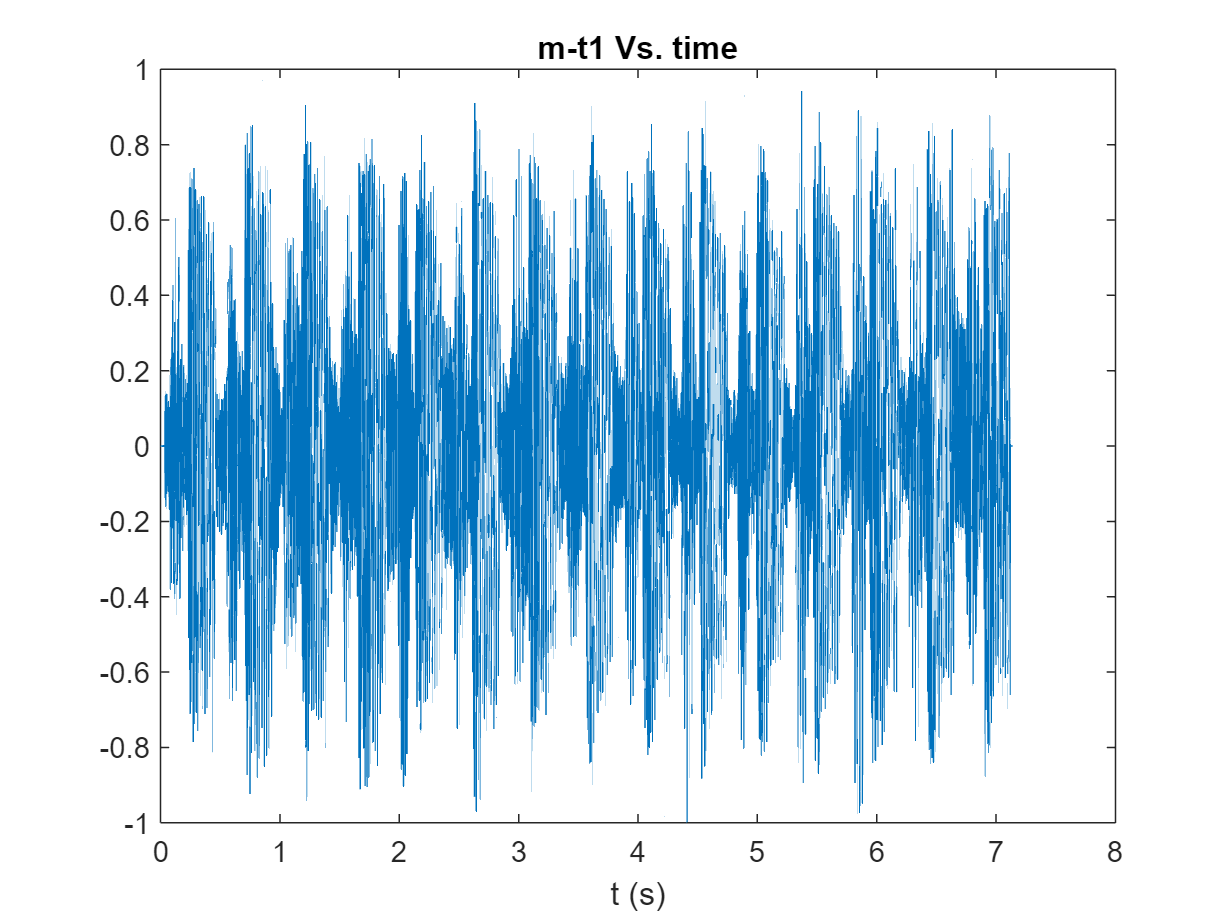

t1 = audioread('m_t1.mp3');
t1 = t1/max(abs(t1));

% sound(t1, FS);

t_1 = (0:length(t1)-1) / FS;
plot(t_1, t1);
xlabel('t (s)');
title('m-t1 Vs. time');

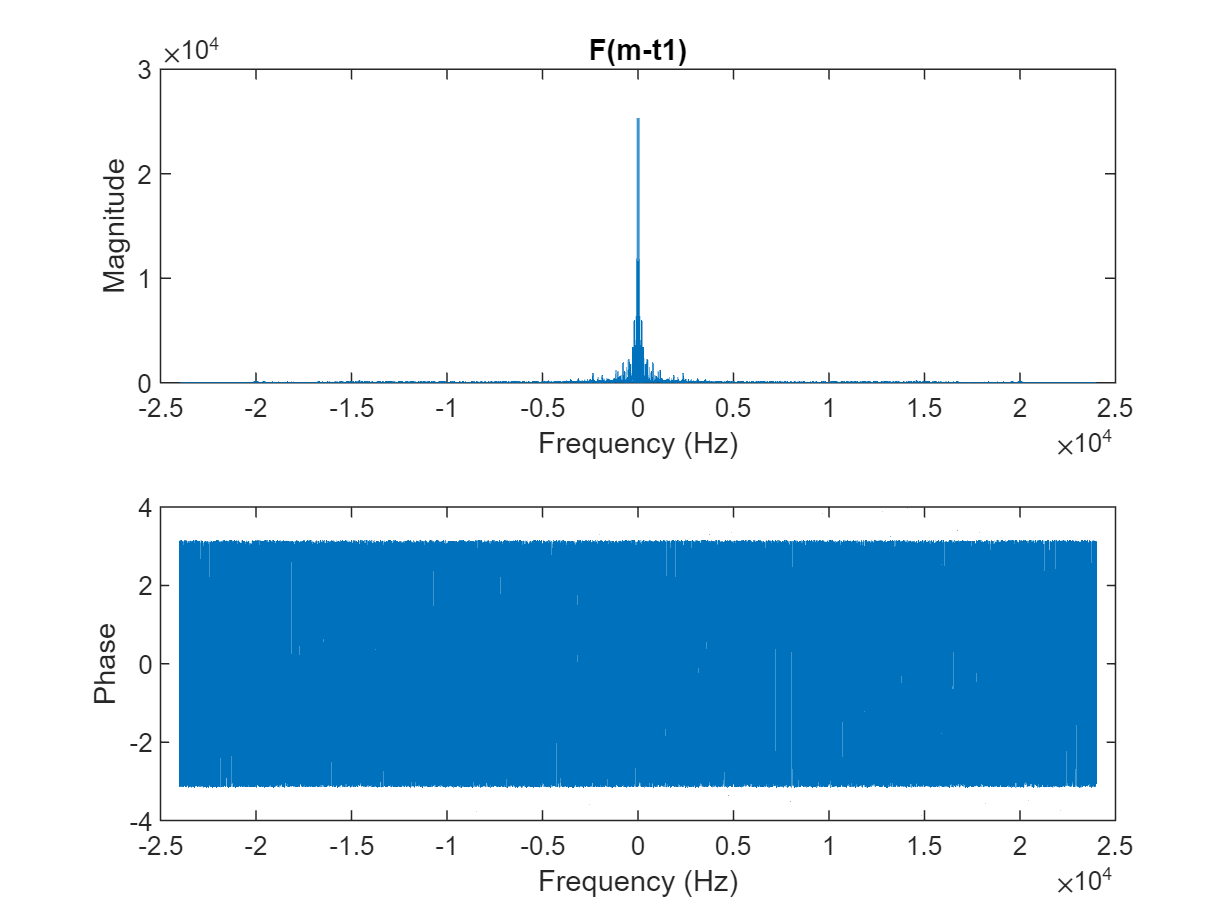


F1 = fftshift(fft(t1));
n_1 = length(t1);
f_1 = (-n_1/2:n_1/2-1)*(FS/n_1);



figure;
subplot(2,1,1);
plot(f_1,abs(F1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(m-t1)');
subplot(2,1,2);
plot(f_1,angle(F1));
xlabel('Frequency (Hz)');
ylabel('Phase');

fprintf("\n max freq. with magnitude -> 20.5 kHz\n");


 max freq. with magnitude -> 20.5 kHz


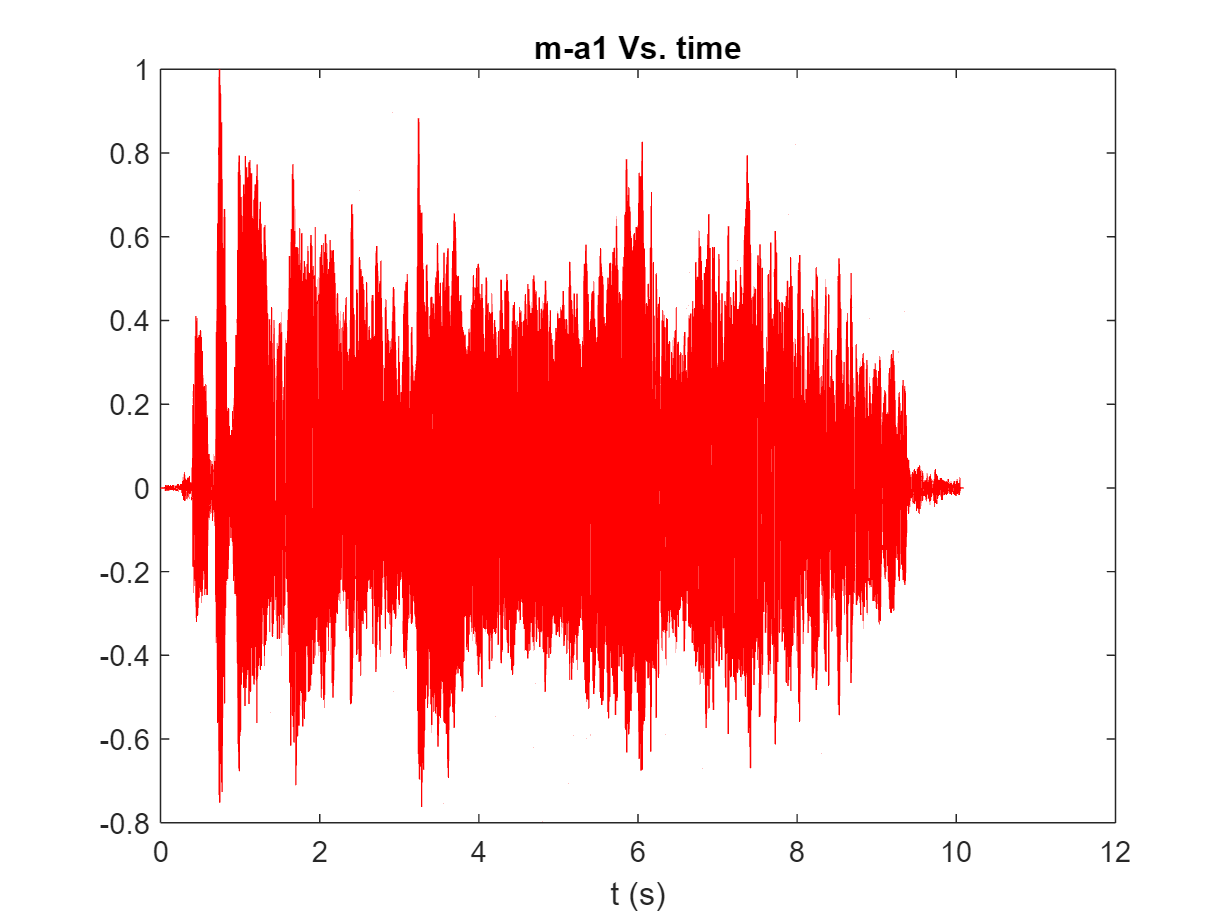

a1 = audioread('m_a1.mp3');
a1 = a1/max(abs(a1));

% sound(a1, FS);

t_2 = (0:length(a1)-1) / FS;
figure;
plot(t_2, a1,'r');
xlabel('t (s)');
title('m-a1 Vs. time');

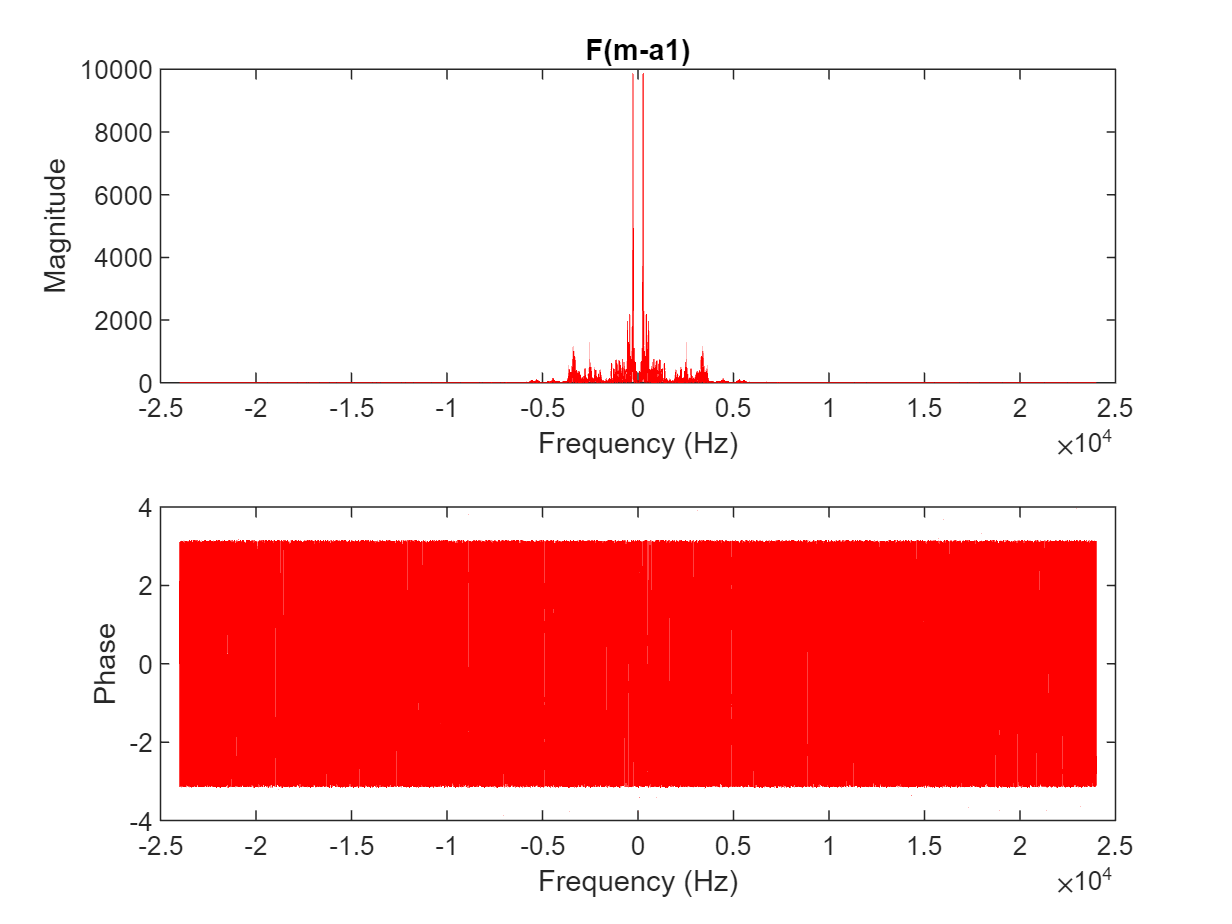


F2 = fftshift(fft(a1));
n_2 = length(a1);
f_2 = (-n_2/2:n_2/2-1)*(FS/n_2);

figure;
subplot(2,1,1);
plot(f_2,abs(F2),'r');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(m-a1)');

subplot(2,1,2);
plot(f_2,angle(F2),'r');
xlabel('Frequency (Hz)');
ylabel('Phase');

fprintf("\n max freq. with magnitude -> 8 kHz\n");


 max freq. with magnitude -> 8 kHz


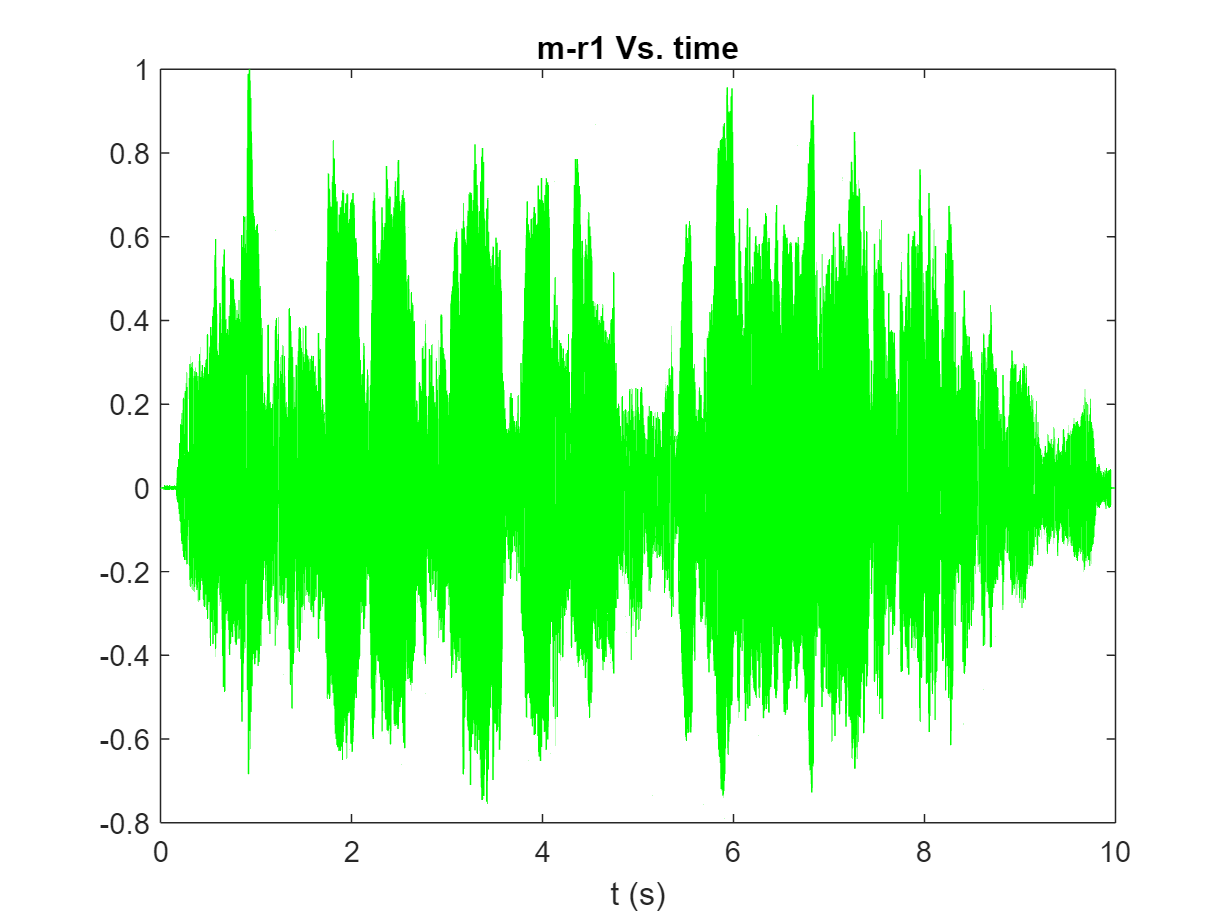

r1 = audioread('m_r1.mp3');
r1 = r1/max(abs(r1));

% sound(r1, FS);

t_3 = (0:length(r1)-1) / FS;
figure;
plot(t_3, r1,'g');
xlabel('t (s)');
title('m-r1 Vs. time');

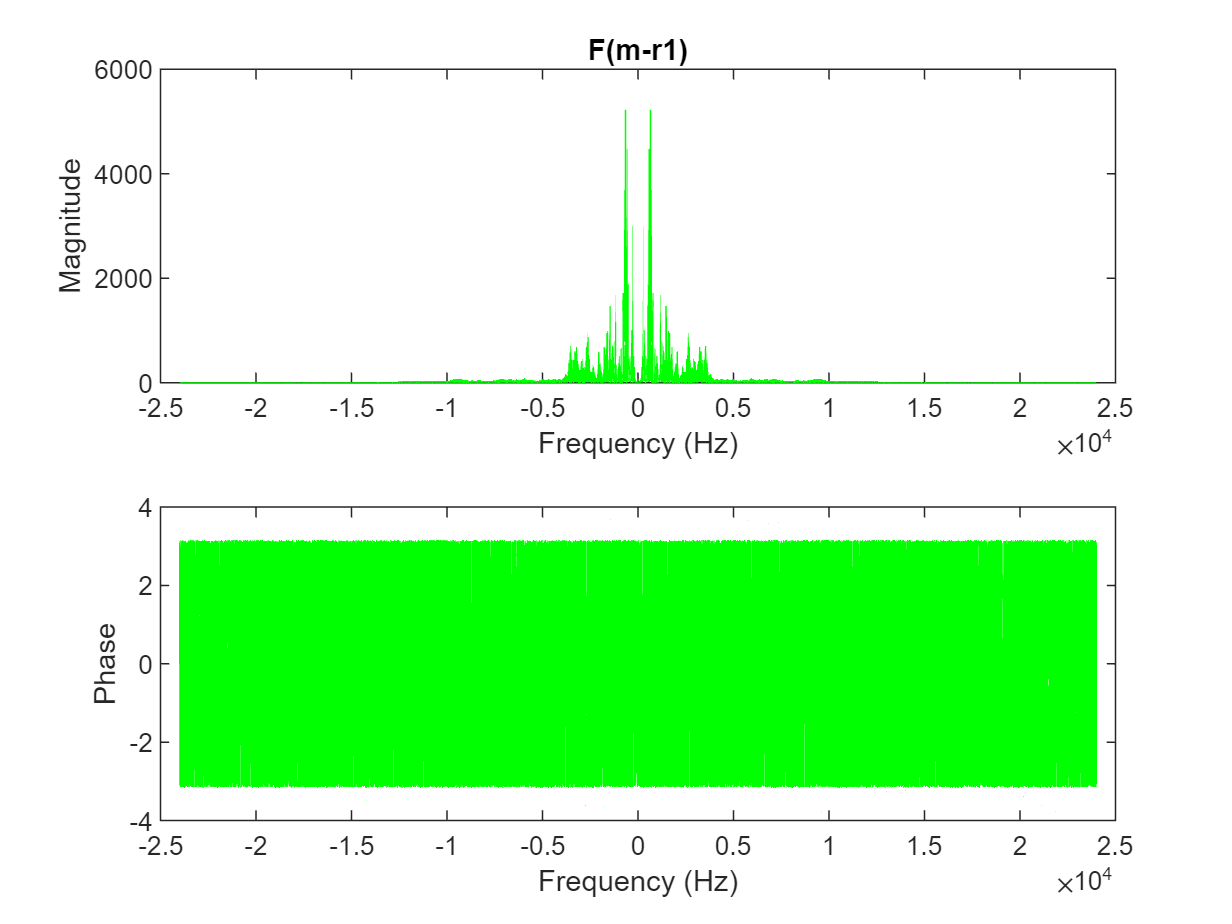


F3 = fftshift(fft(r1));
n_3 = length(r1);
f_3 = (-n_3/2:n_3/2-1)*(FS/n_3);

figure;
subplot(2,1,1);
plot(f_3,abs(F3),'g');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(m-r1)');

subplot(2,1,2);
plot(f_3,angle(F3),'g');
xlabel('Frequency (Hz)');
ylabel('Phase');

fprintf("\n max freq. with magnitude -> 13 kHz\n");


 max freq. with magnitude -> 13 kHz


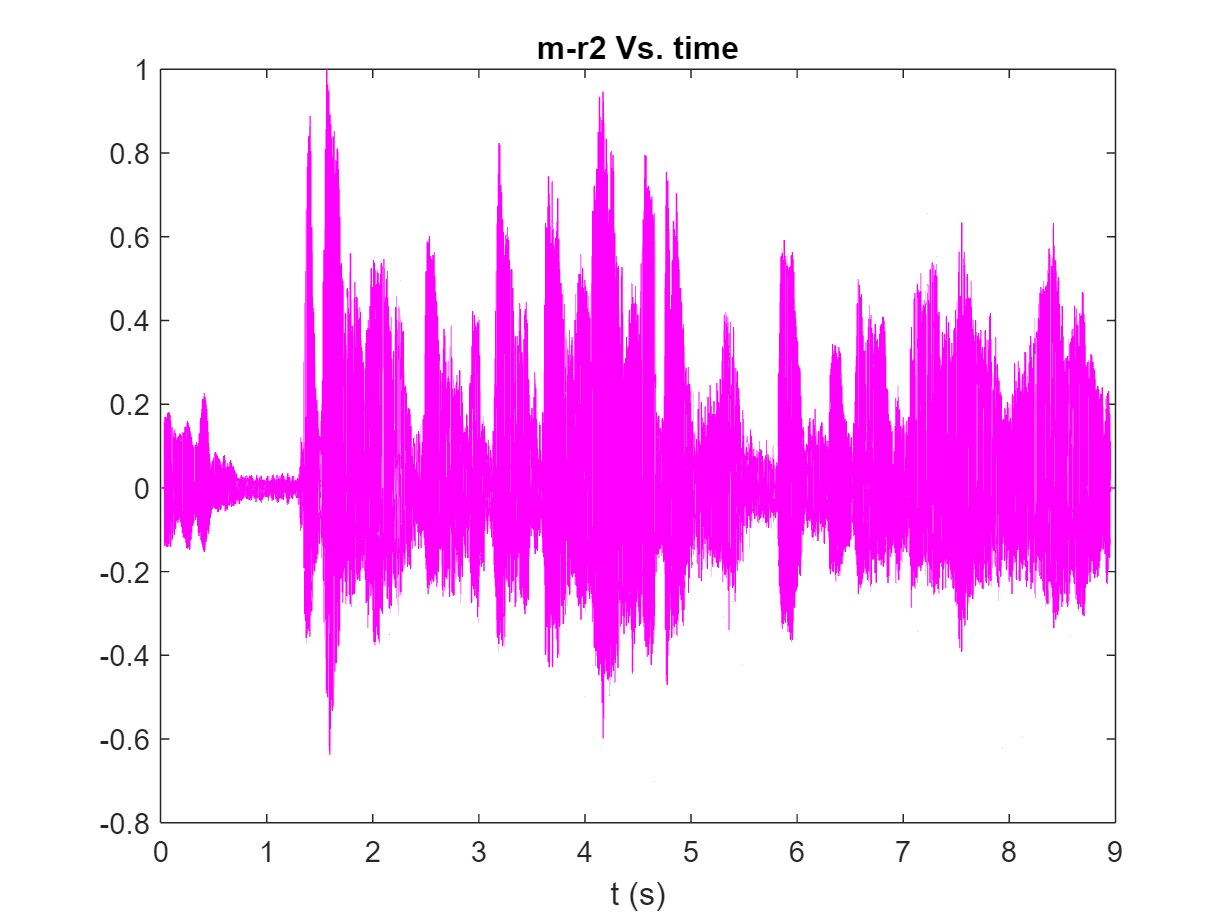

r2 = audioread('m_r2.mp3');
r2 = r2/max(abs(r2));

% sound(r2, FS);

t_4 = (0:length(r2)-1) / FS;
figure;
plot(t_4, r2,'m');
xlabel('t (s)');
title('m-r2 Vs. time');

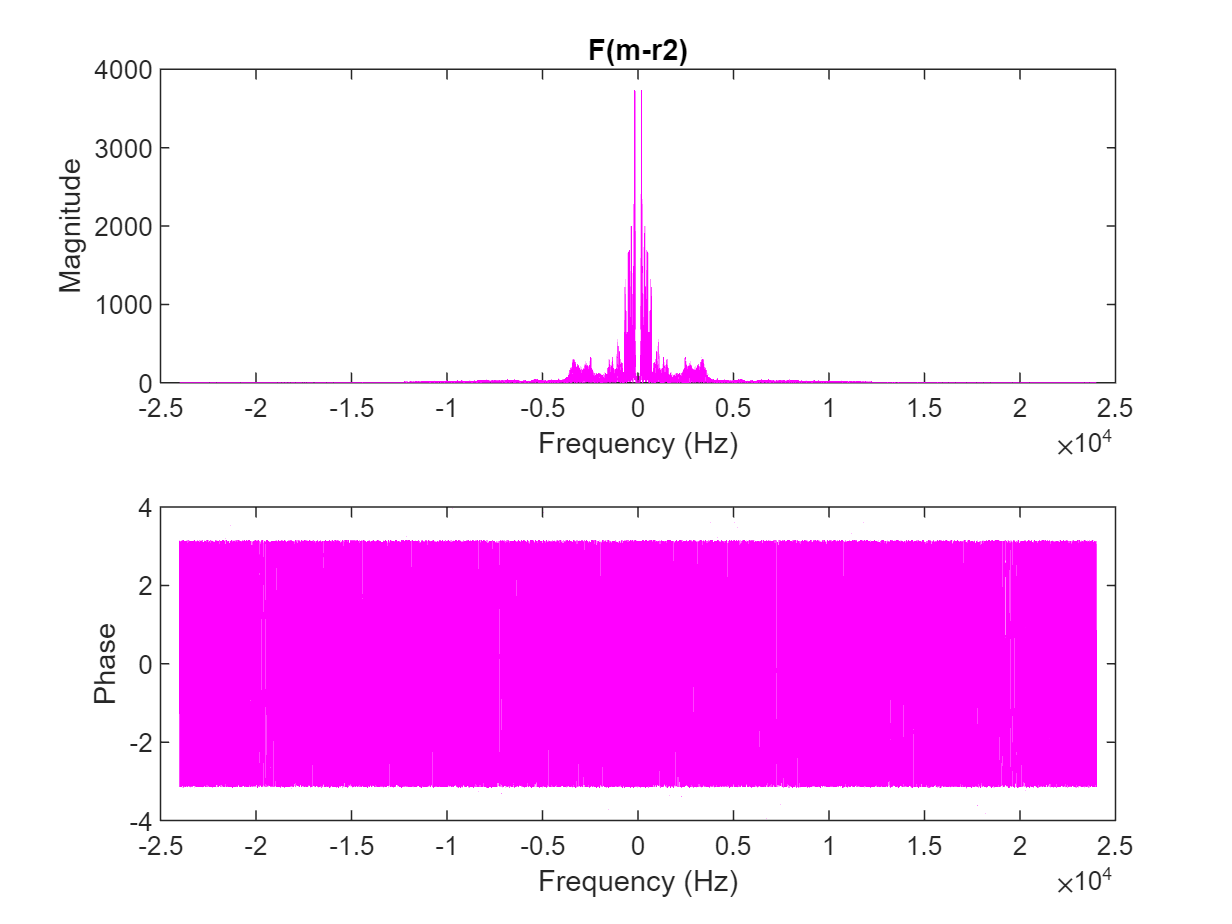


F4 = fftshift(fft(r2));
n_4 = length(r2);
f_4 = (-n_4/2:n_4/2-1)*(FS/n_4);

figure;
subplot(2,1,1);
plot(f_4,abs(F4),'m');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(m-r2)');

subplot(2,1,2);
plot(f_4,angle(F4),'m');
xlabel('Frequency (Hz)');
ylabel('Phase');

fprintf("\n max freq. with magnitude -> 15 kHz\n");


 max freq. with magnitude -> 15 kHz


***B:***

- **LP @ 300 Hz**

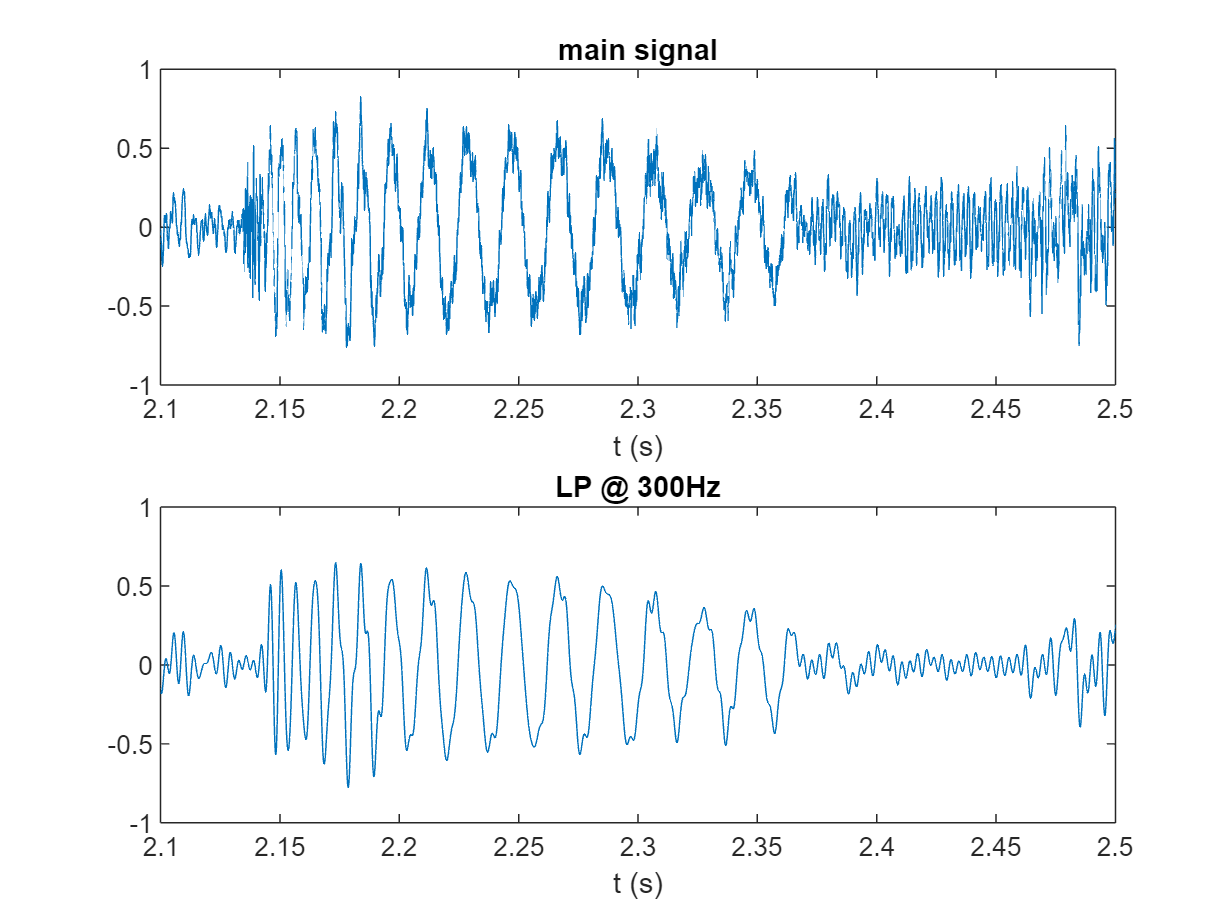

filtered_F1_300 = LPfilter(F1, f_1, 300);
filtered_t1_300 = ifft(ifftshift(filtered_F1_300));

% sound(filtered_t1_300, FS);

figure;
subplot(2,1,1);
plot(t_1, t1);
title('main signal');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(2,1,2);
plot(t_1,real(filtered_t1_300));
title('LP @ 300Hz');
xlabel('t (s)');
xlim([2.1 2.5]);

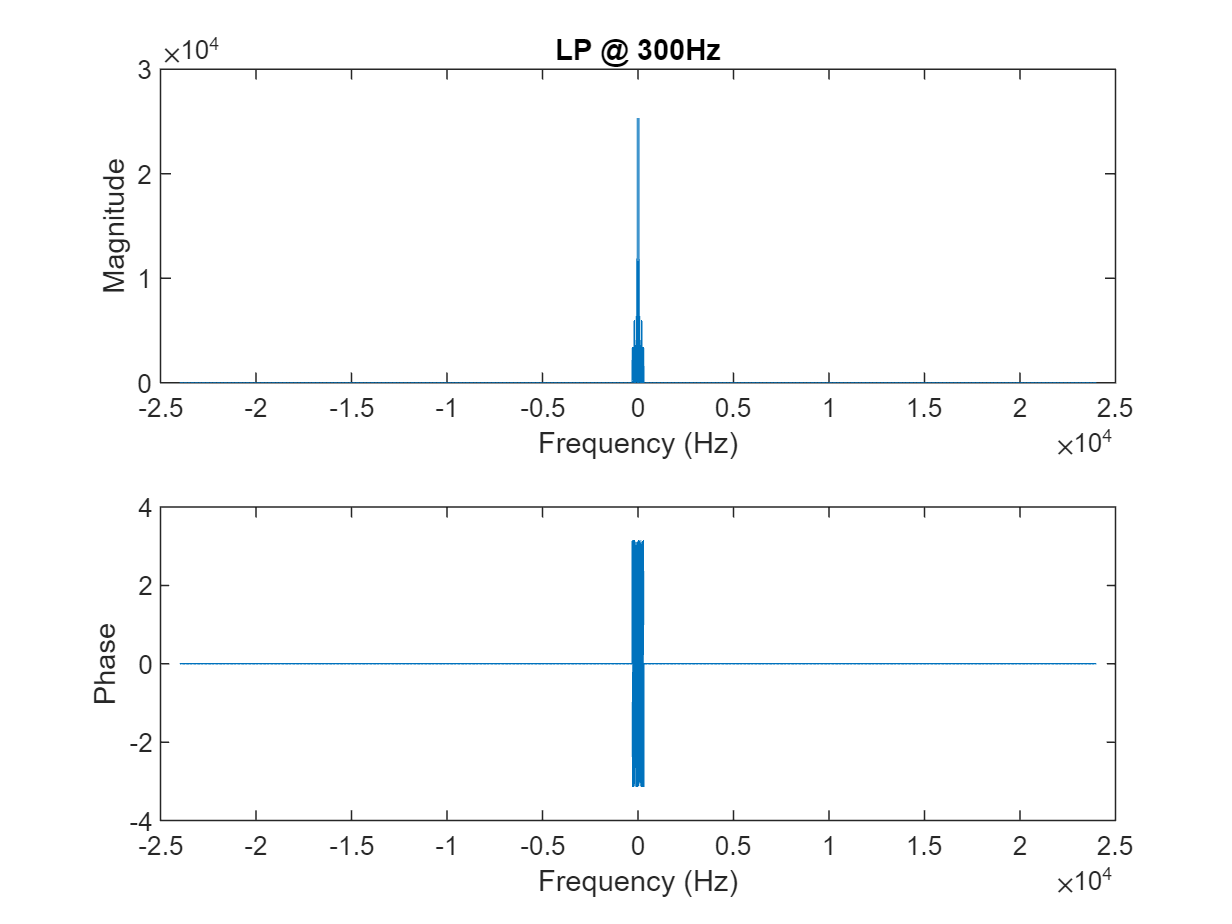



figure;
subplot(2,1,1);
plot(f_1,abs(filtered_F1_300));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 300Hz');
subplot(2,1,2);
plot(f_1,angle(filtered_F1_300));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **LP @ 800 Hz**

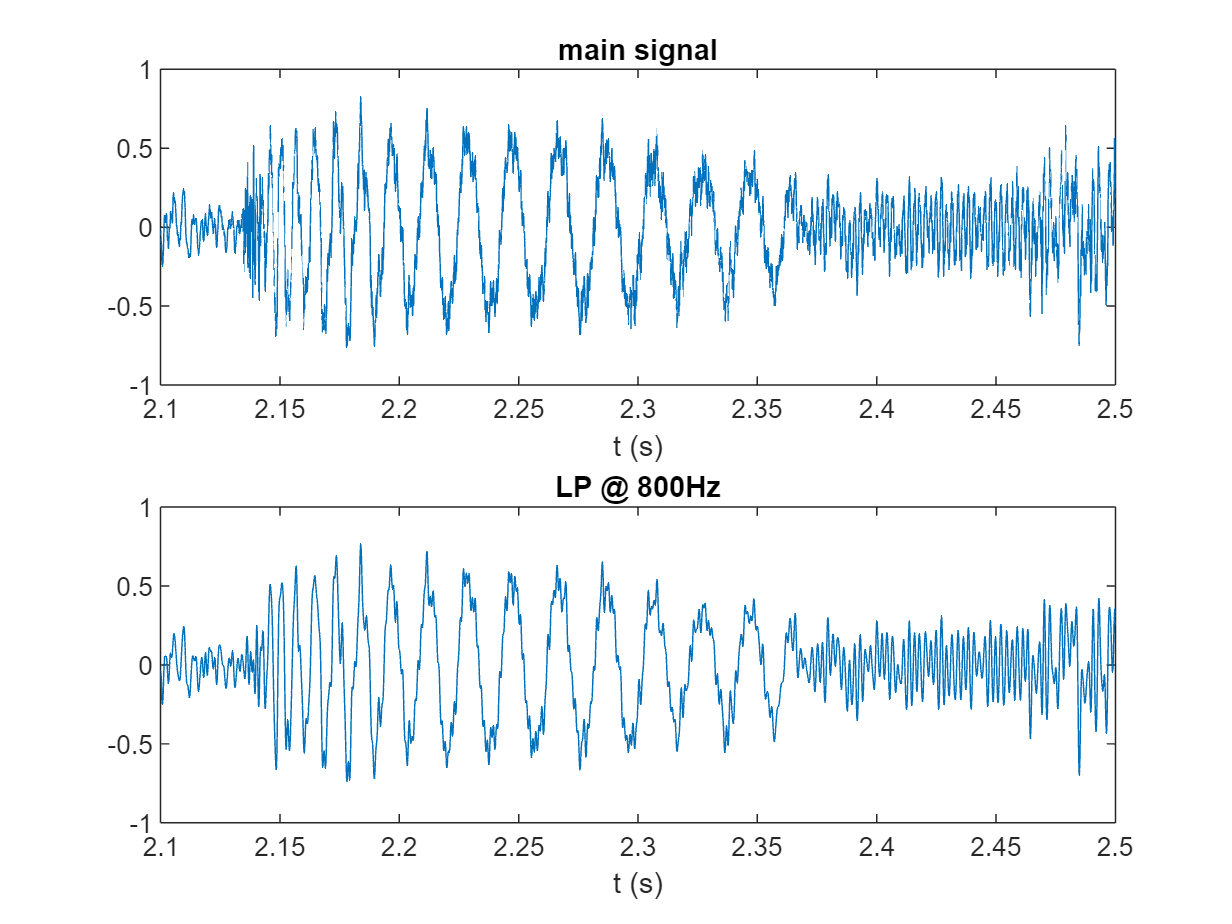

filtered_F1_800 = LPfilter(F1, f_1, 800);
filtered_t1_800 = ifft(ifftshift(filtered_F1_800));
% sound(filtered_t1_800, FS);

figure;
subplot(2,1,1);
plot(t_1, t1);
title('main signal');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(2,1,2);
plot(t_1,real(filtered_t1_800));
title('LP @ 800Hz');
xlabel('t (s)');
xlim([2.1 2.5]);

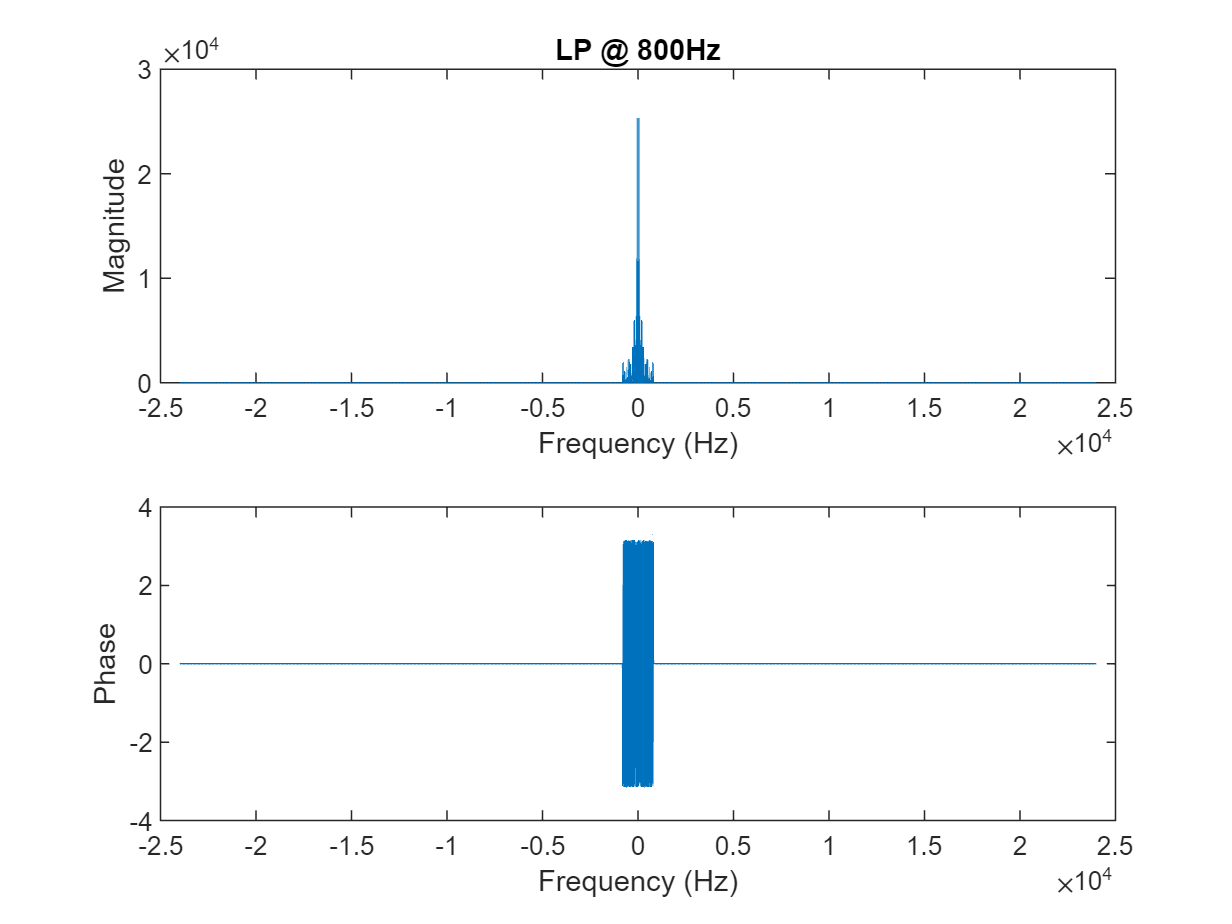


figure;
subplot(2,1,1);
plot(f_1,abs(filtered_F1_800));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 800Hz');
subplot(2,1,2);
plot(f_1,angle(filtered_F1_800));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **LP @ 5k Hz**

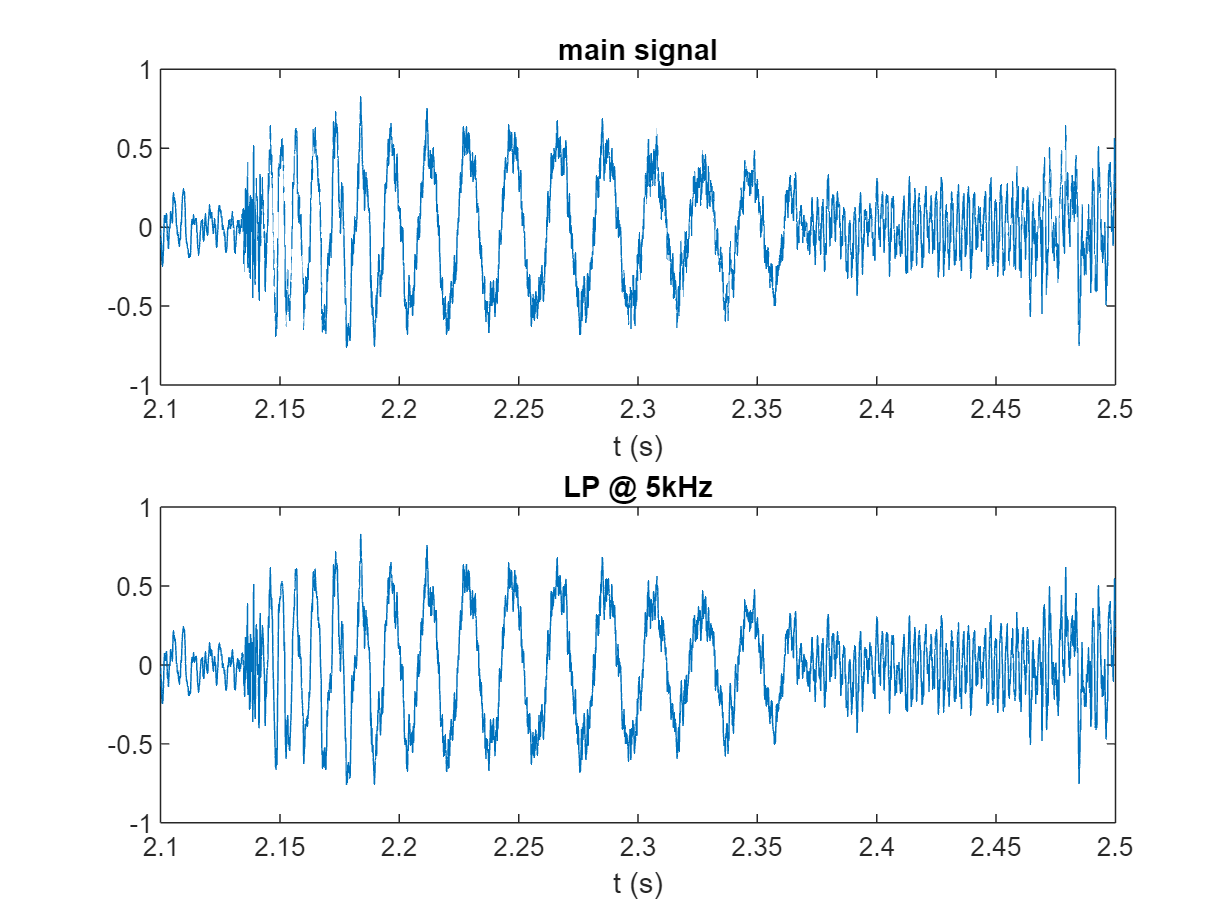

filtered_F1_5k = LPfilter(F1, f_1, 5000);
filtered_t1_5k = ifft(ifftshift(filtered_F1_5k));
% sound(filtered_t1_5k, FS);

figure;
subplot(2,1,1);
plot(t_1, t1);
title('main signal');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(2,1,2);
plot(t_1,real(filtered_t1_5k));
title('LP @ 5kHz');
xlabel('t (s)');
xlim([2.1 2.5]);

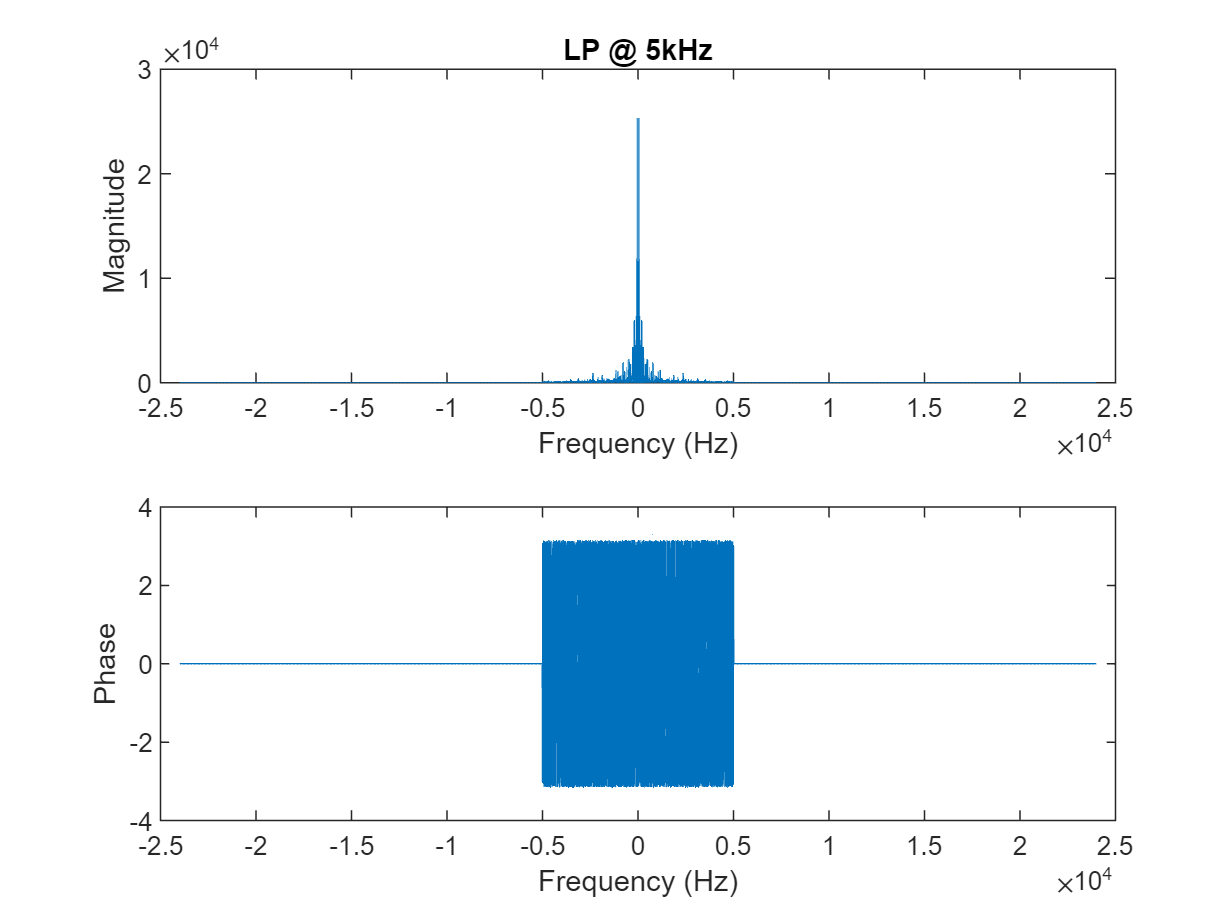


figure;
subplot(2,1,1);
plot(f_1,abs(filtered_F1_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 5kHz');
subplot(2,1,2);
plot(f_1,angle(filtered_F1_5k));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **LP @ 10k Hz**

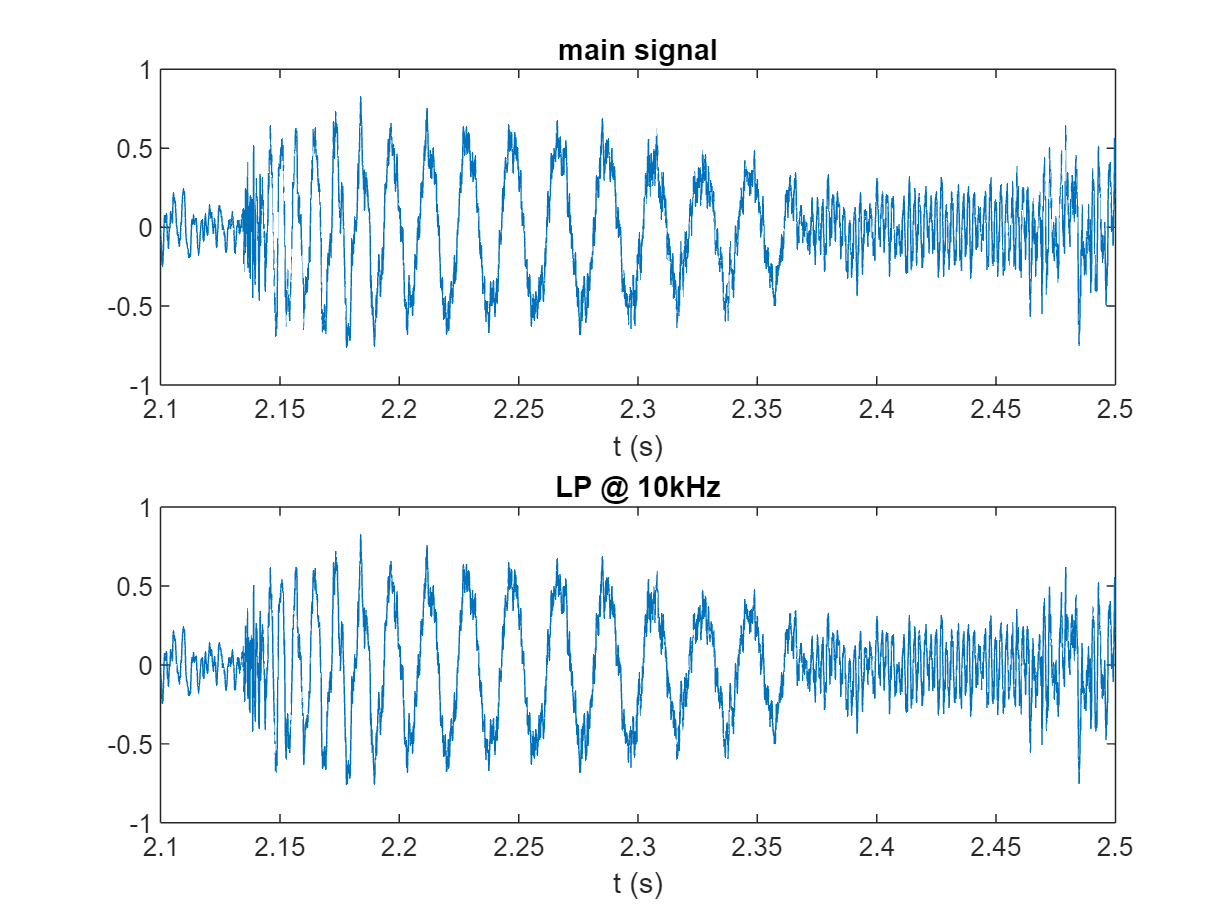

filtered_F1_10k = LPfilter(F1, f_1, 10000);
filtered_t1_10k = ifft(ifftshift(filtered_F1_10k));
% sound(filtered_t1_10k, FS);

figure;
subplot(2,1,1);
plot(t_1, t1);
title('main signal');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(2,1,2);
plot(t_1,real(filtered_t1_10k));
title('LP @ 10kHz');
xlabel('t (s)');
xlim([2.1 2.5]);

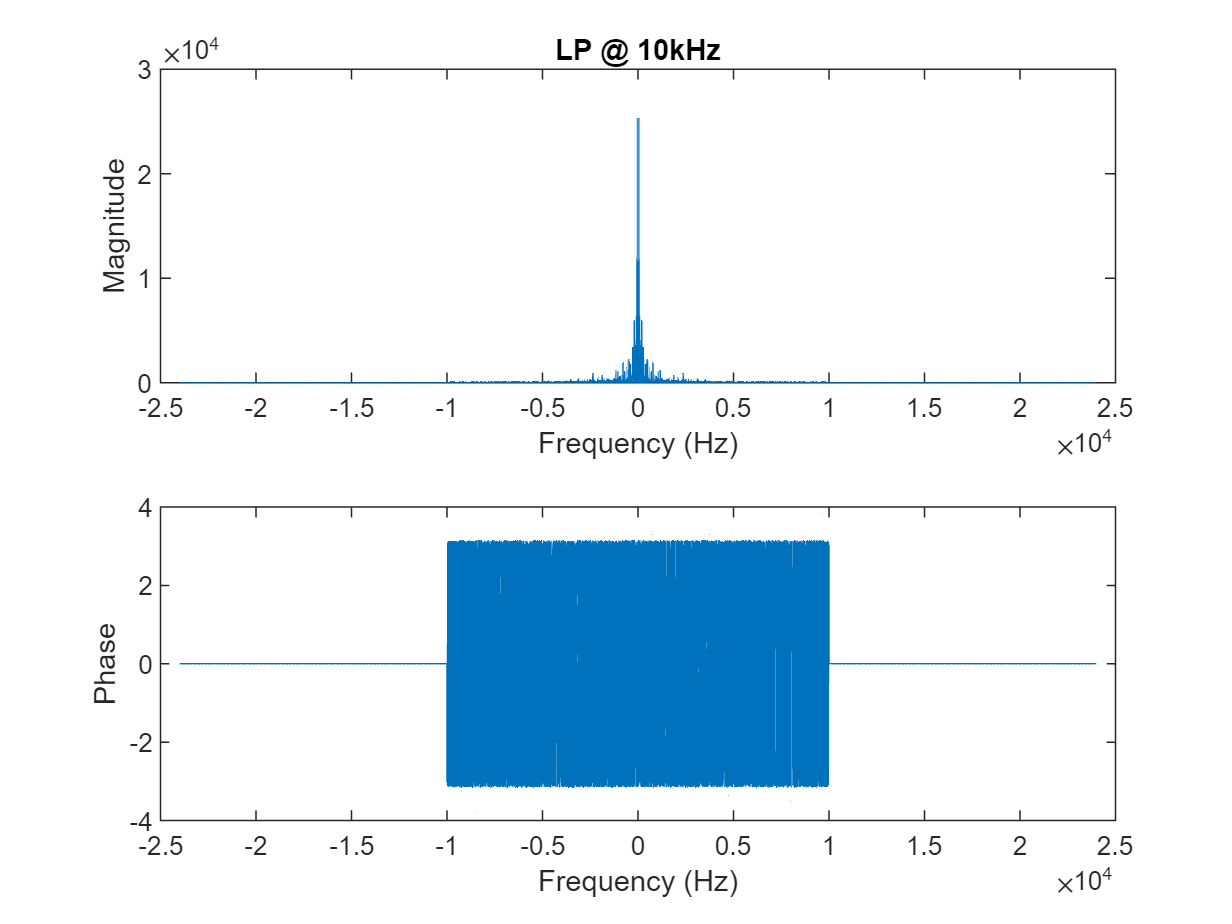


figure;
subplot(2,1,1);
plot(f_1,abs(filtered_F1_10k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 10kHz');
subplot(2,1,2);
plot(f_1,angle(filtered_F1_10k));
xlabel('Frequency (Hz)');
ylabel('Phase');

**All together!**

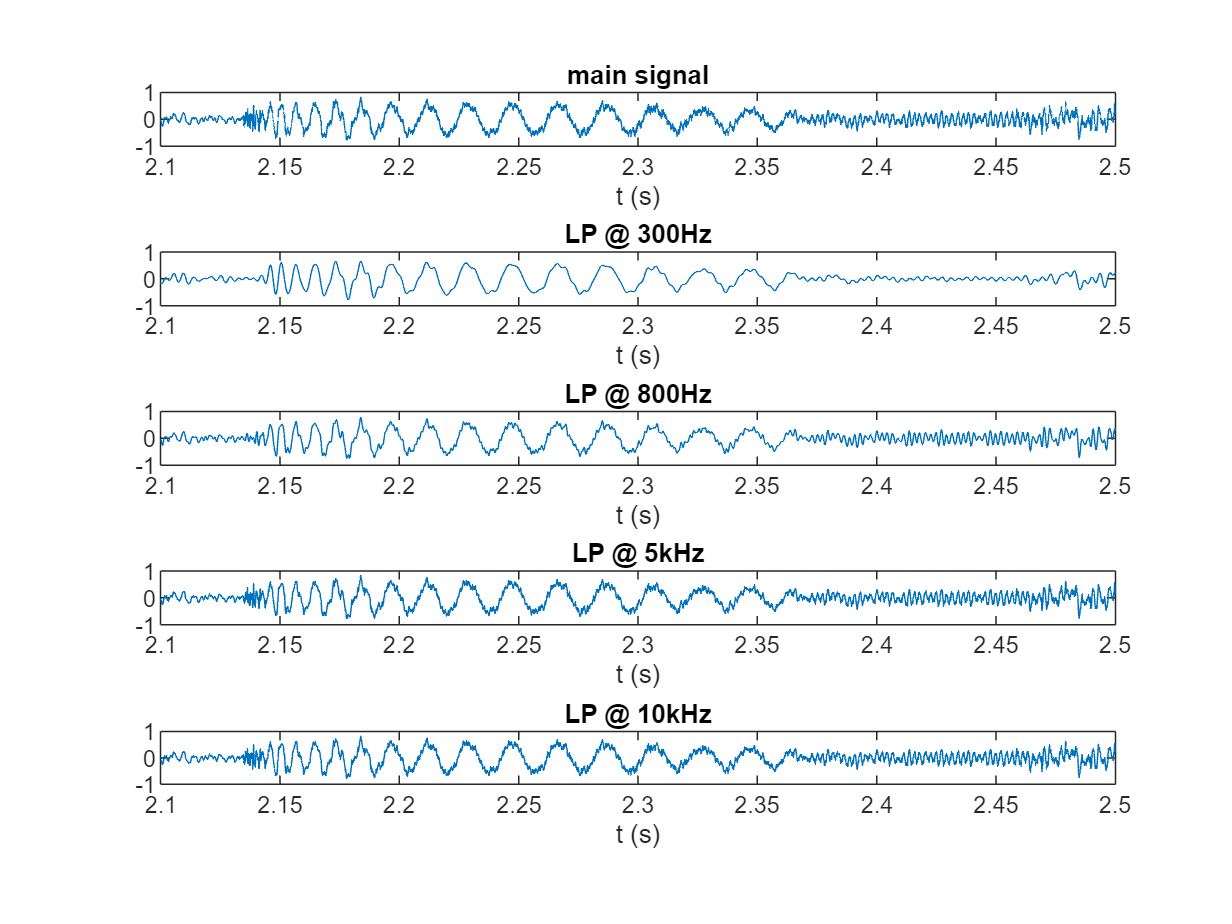

figure;
subplot(5,1,1);
plot(t_1, t1);
title('main signal');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(5,1,2);
plot(t_1,real(filtered_t1_300));
title('LP @ 300Hz');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(5,1,3);
plot(t_1,real(filtered_t1_800));
title('LP @ 800Hz');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(5,1,4);
plot(t_1,real(filtered_t1_5k));
title('LP @ 5kHz');
xlabel('t (s)');
xlim([2.1 2.5]);
subplot(5,1,5);
plot(t_1,real(filtered_t1_10k));
title('LP @ 10kHz');
xlabel('t (s)');
xlim([2.1 2.5]);

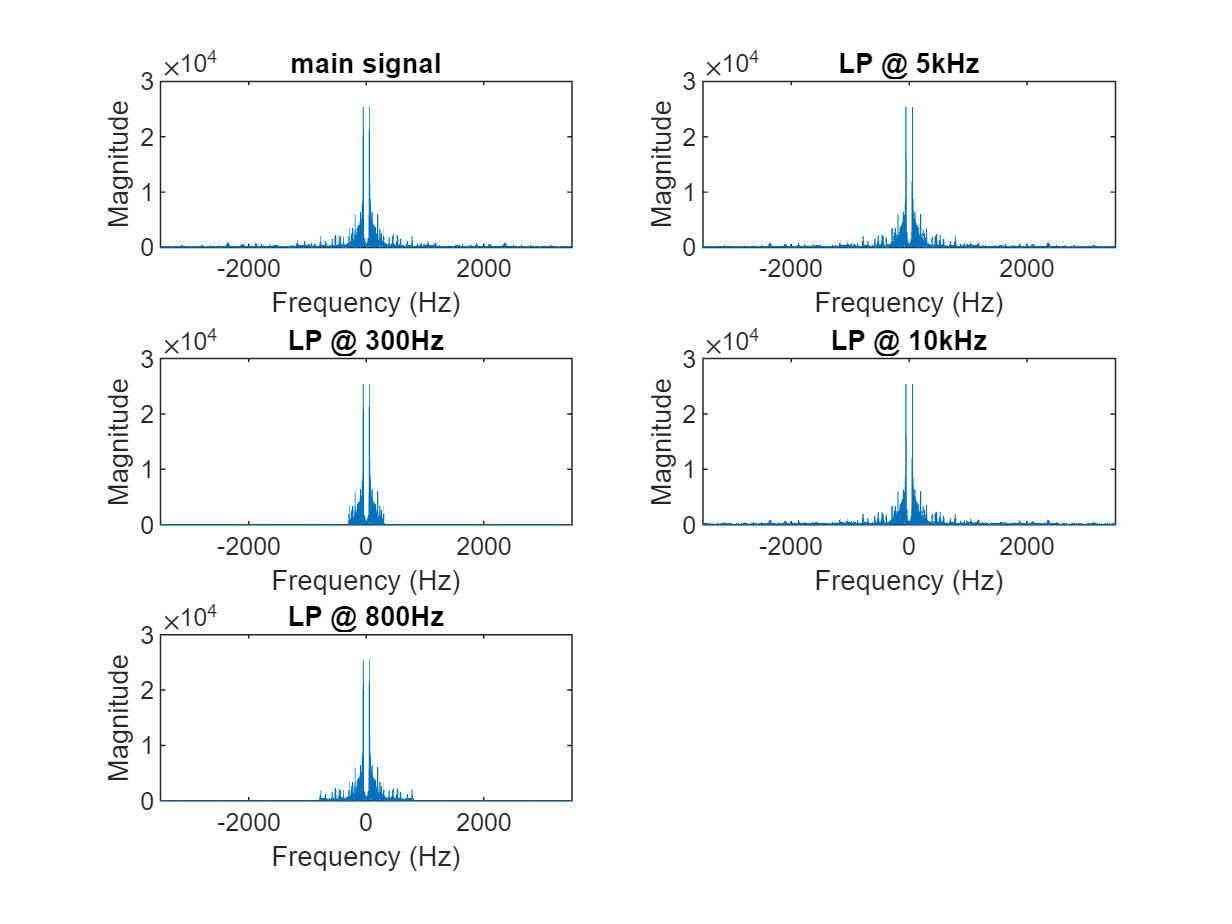

figure;
subplot(3,2,1);
plot(f_1,abs(F1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('main signal');
xlim([-3.5e3 3.5e3]);
subplot(3,2,3);
plot(f_1,abs(filtered_F1_300));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 300Hz');
xlim([-3.5e3 3.5e3]);
subplot(3,2,5);
plot(f_1,abs(filtered_F1_800));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 800Hz');
xlim([-3.5e3 3.5e3]);
subplot(3,2,2);
plot(f_1,abs(filtered_F1_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 5kHz');
xlim([-3.5e3 3.5e3]);
subplot(3,2,4);
plot(f_1,abs(filtered_F1_10k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('LP @ 10kHz');
xlim([-3.5e3 3.5e3]);

% sound(t1, FS);
% sound(filtered_t1_300, FS);
% sound(filtered_t1_800, FS);
% sound(filtered_t1_5k, FS);
% sound(filtered_t1_10k, FS);

function New_F = LPfilter(pre_F,freq_vector, f)
    n = length(freq_vector);
    New_F=zeros(n,1);
    for i = (1:n)
        if(abs(freq_vector(i)) < f)
            New_F(i)=pre_F(i); 
        end
    end
end